# Sample 7-3

## 幾何学処理

拡大処理

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Geometric image processing

Interpolation

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

close all

### 補間率の設定

(Setting of upsampling factor)

- $M$: 補間率 (upsampling factor) 

% Upsampling factor
uFactor = 2;

% Upsampling phase
uPhase = 0;

最近傍補間フィルタのインパルス応答 (Impulse response of nearest-neighbor filter)

        
$$f[n]=\left\{\begin{array}{ll} 1& 0\leq n\leq M-1 \\ 0 & \mathrm{otherwise} \end{array}\right.$$


一次補間フィルタのインパルス応答 (Impulse response of linear interpolation filter)

        
$$f[n]=\left\{\begin{array}{ll} \frac{1}{M}(M-|n|) & -M+1\leq n\leq M-1 \\ 0 & \mathrm{otherwise} \end{array}\right.$$


オフセットを考慮した場合 (When considering the offset)

        
$$f[n]=\left\{\begin{array}{ll} \frac{1}{M}\left(M-\left|n-\frac{1}{2}\right|\right) & -M+1\leq n\leq M \\ 0 & \mathrm{otherwise} \end{array}\right.$$


ただし，非因果性に注意．(Note that the incausal property.)

- $\{f[n]\}_n$: インパルス応答 (Impulse response)

% Filter seletion
ftype = "Nearest neighbor";
offset = false; % Set TRUE for even M, FALSE for odd M to make the handmade bilinear interpolation similar to IMRESIZE

% Impulse response of interpolation filter
if strcmp(ftype,'Nearest neighbor')
    f = ones(1,uFactor);
    offset = false;
elseif strcmp(ftype, 'Bilinear interpolation')
    if ~offset
         f = 1-abs((-uFactor+1):(uFactor-1))/uFactor;
    else
        f = 1-abs(((-uFactor+1):uFactor)-0.5)/uFactor;
    end
else
    error('Invalid ftype')
end

## フィルタ特性の表示

(Display of filter characteristics)

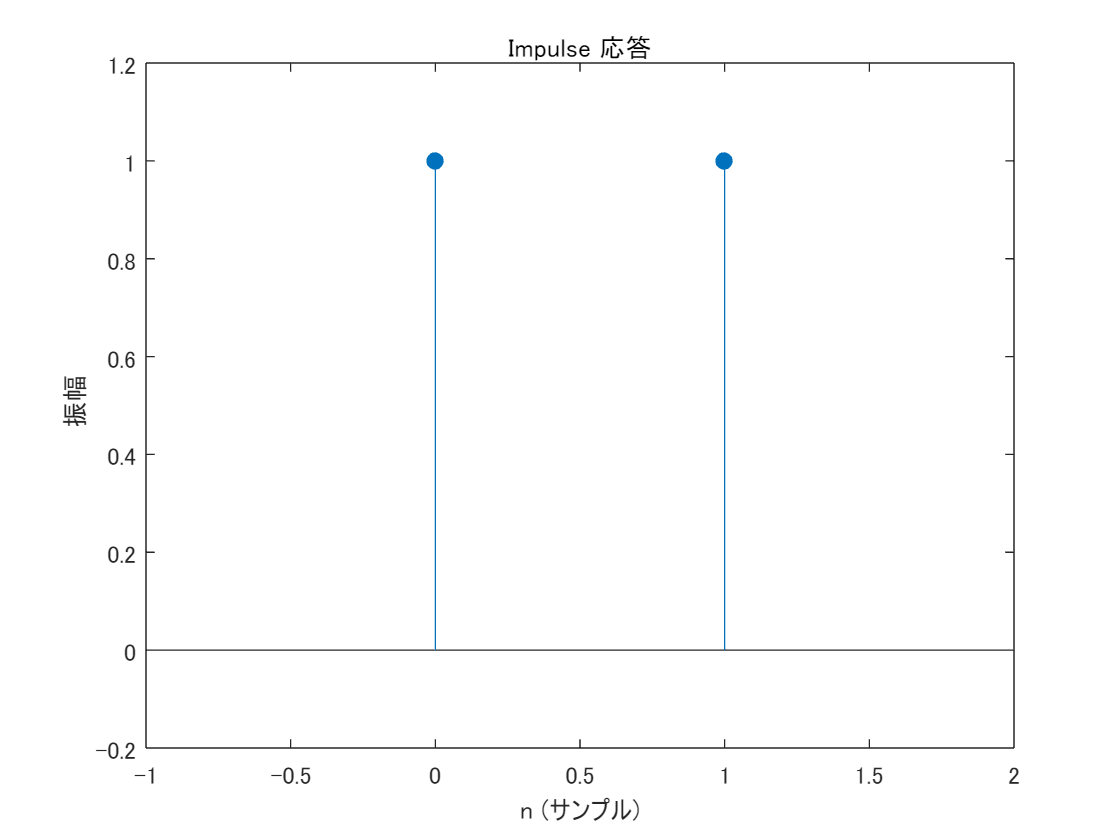

% Impulse response
figure(1)
impz(f)
ax = gca;
ax.XLim = [-1 length(f)];
ax.YLim = [-0.2 1.2];

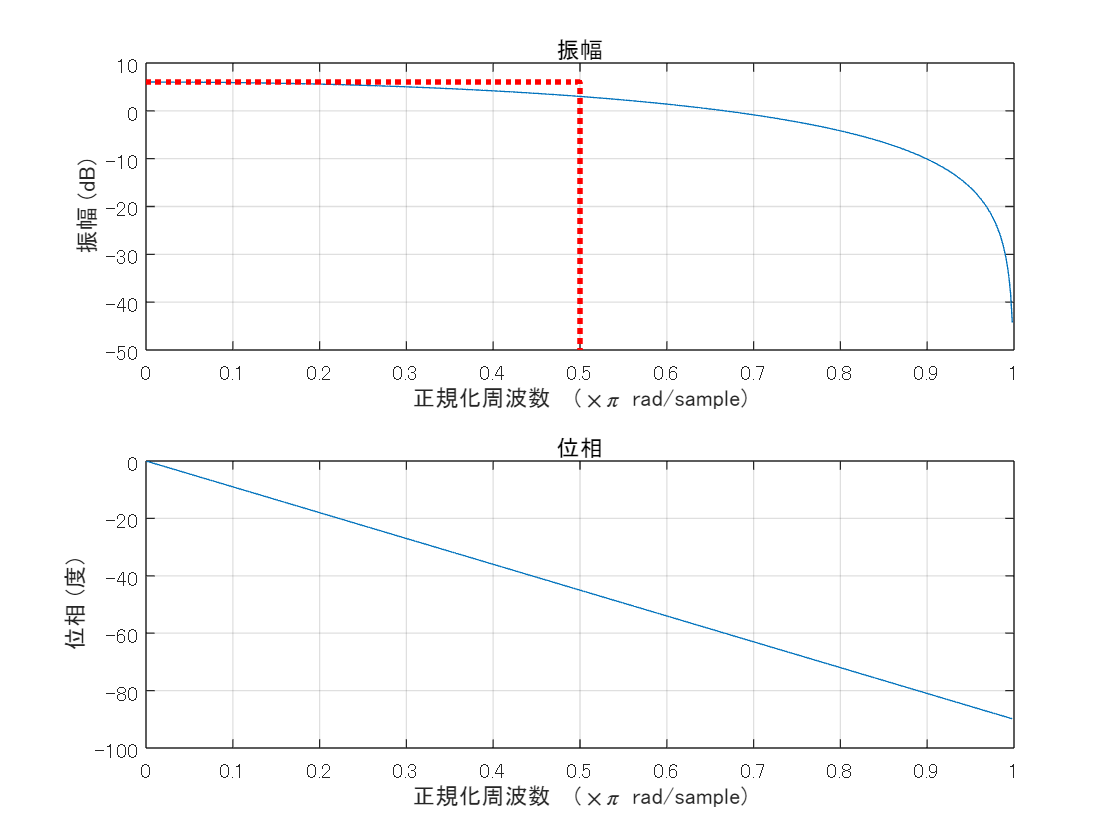

% Frequency response
figure(2)
freqz(f)
ax = gca;
hold on
line([0 1/uFactor 1/uFactor],[20*log10(uFactor) 20*log10(uFactor) ax.YLim(1)],...
    'LineStyle',':','LineWidth',2,'Color','red');
hold off

### 画像への適用

(Application to images)

        
$$v[\mathbf{m}]=\sum_{\mathbf{k}\in\mathbb{Z}^2}u[\mathbf{Mk}]f[\mathbf{m}-\mathbf{Mk}]$$


最近傍補間フィルタのインパルス応答 (Impulse response of nearest-neighbor filter)

        
$$f[\mathbf{n}]=\left\{\begin{array}{ll} 1 & \mathbf{n}\in \mathcal{N}(\mathbf{M})\\ 0 & \mathrm{otherwise} \end{array}\right.$$


双一次補間フィルタのインパルス応答 (Impulse response of bilinear interpolation filter)

        
$$f[\mathbf{n}]=\left\{\begin{array}{ll} \mathrm{prod}\left(\mathbf{1}-\mathrm{abs}\left(\mathbf{M}^{-1}\mathbf{n}\right) \right)& \mathbf{n}\in \{\mathbf{Mx}\in\mathbb{Z}^2\ |\ \mathbf{x}\in(-1,1)^2\} \\ 0 & \mathrm{otherwise} \end{array}\right.$$


オフセットを考慮した場合

        
$$f[\mathbf{n}]=\left\{\begin{array}{ll} \mathrm{prod}\left(\mathbf{1}-\mathrm{abs}\left(\mathbf{M}^{-1}\mathbf{n}-\frac{1}{2}\mathbf{1}\right) \right)& \mathbf{n}\in \{\mathbf{Mx}\in\mathbb{Z}^2\ |\ \mathbf{x}\in(-1,1]^2\} \\ 0 & \mathrm{otherwise} \end{array}\right.$$


ただし， $\mathrm{prod}(\cdot)$ は要素の積．非因果性に注意．(where $\mathrm{prod}(\cdot)$ denotes the product of the array elements. Note that the incausal property.)

Note that if $\mathbf{M}=\mathrm{diag}(M,M)\Rightarrow \mathrm{prod}(\mathbf{1}-\mathrm{abs}(\mathbf{M}^{-1}\mathbf{n}-\alpha\mathbf{1}))=\frac{1}{M^2}(M-|n_1-\alpha|)(M-|n_2-\alpha|)$ , $\{\mathbf{Mx}\in\mathbb{Z}^2\ |\ \mathbf{x}\in(-1,1)^2\}=\{-M+1,-M+2,\cdots,M-1\}^2$ and $\{\mathbf{Mx}\in\mathbb{Z}^2\ |\ \mathbf{x}\in(-1,1]^2\}=\{-M+1,-M+2,\cdots,M\}^2$.

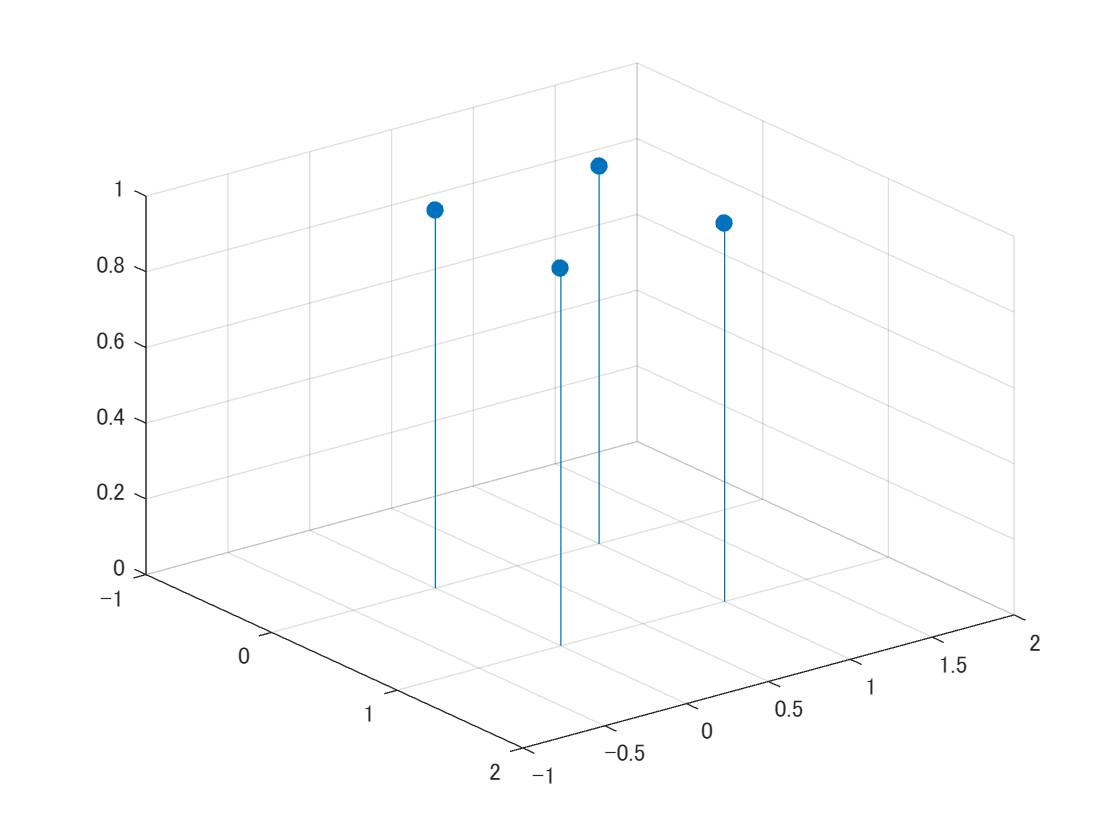

% Reading an image
u = imread('cameraman.tif');

% Generating an interpolation filter
if strcmp(ftype,'Nearest neighbor')
    [n1,n2] = ndgrid(0:uFactor-1);
    f = ones(uFactor,uFactor);
elseif strcmp(ftype,'Bilinear interpolation')
    if ~offset
        [n1,n2] = ndgrid(-uFactor+1:uFactor-1);
        f = (1-abs(n1)/uFactor).*(1-abs(n2)/uFactor);
    else
        [n1,n2] = ndgrid(-uFactor+1:uFactor);
        f = (1-abs(n1-0.5)/uFactor).*(1-abs(n2-0.5)/uFactor);
    end
else
    error('Invalid ftype')
end
figure(3)
stem3(n2,n1,f,'filled')
axis ij
ax = gca;
ax.XLim = ax.XLim + [-1 1];
ax.YLim = ax.YLim + [-1 1];

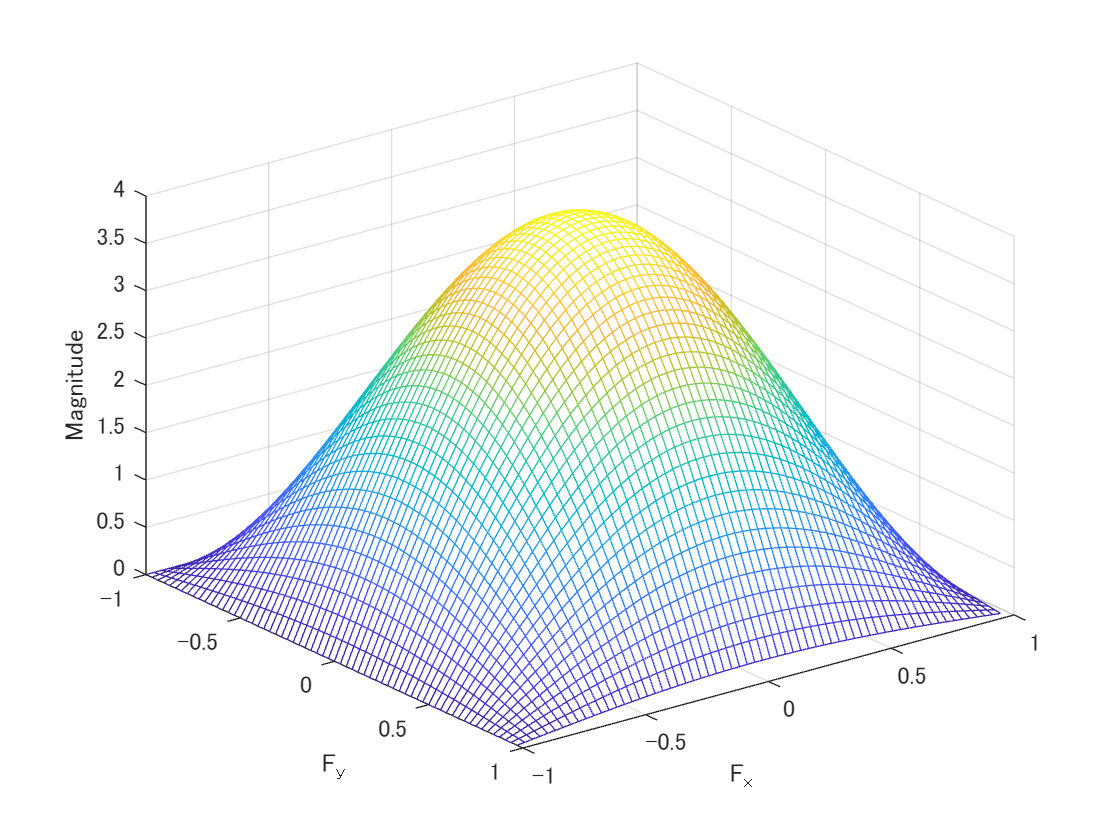

figure(4)
freqz2(f)
axis ij


% Bivariate upsampling function
upsample2 = @(x,n,phase) ...
    shiftdim(upsample(...
    shiftdim(upsample(x,...
    n(1),phase(1)),1),...
    n(2),phase(2)),1);

% Interpolation with upsampling and filtering
x = padarray(u,[1 1],'replicate','both');
w = imfilter(upsample2(x,uFactor*[1 1],uPhase*[1 1]),f,'conv');
s = ceil(uFactor/2);
v = w(s+1:s+uFactor*size(u,1),s+1:s+uFactor*size(u,2));

% Interpolation with IMRESIZE
if strcmp(ftype,'Nearest neighbor')
    y = imresize(u,uFactor,'nearest');
elseif strcmp(ftype, 'Bilinear interpolation')
    y = imresize(u,uFactor,'bilinear');
else
    error('Invalid ftype')
end


### 画像表示

(Display image)

原画像 (Original)

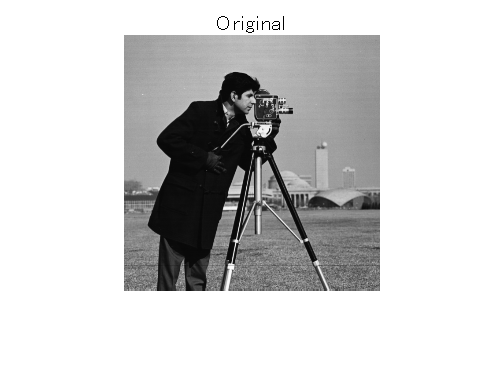

figure(5)
imshow(u)
title('Original')

拡大画像 (Interpolated image)

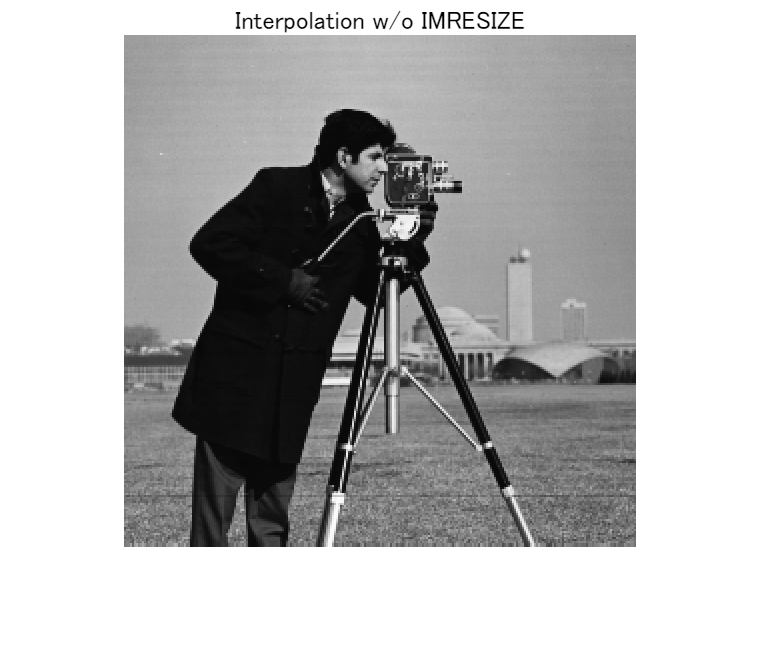

% Definition of MSE
mymse = @(x,y) sum((x-y).^2,'all')/numel(x);

% Display results
figure(6)
imshow(v)
title('Interpolation w/o IMRESIZE')

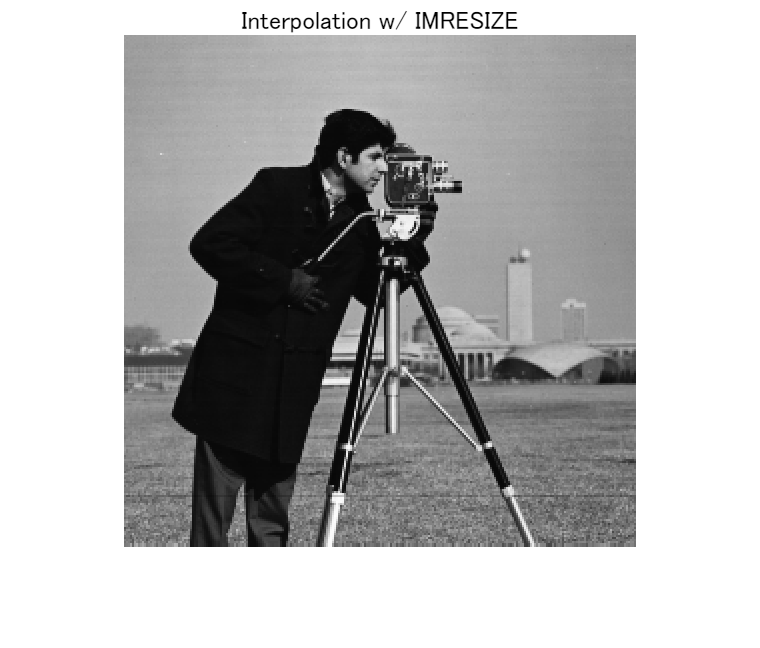

figure(7)
imshow(y)
title('Interpolation w/ IMRESIZE')

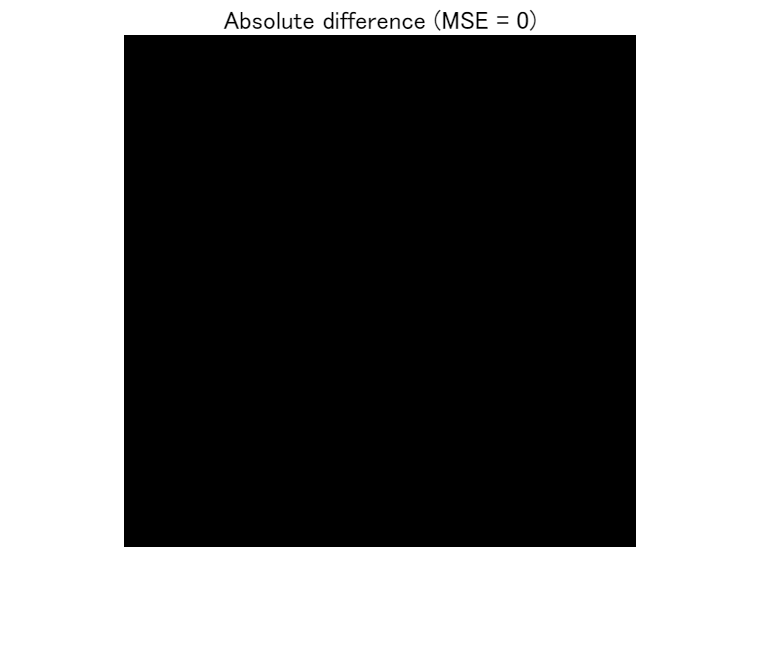

figure(8)
imshow(imabsdiff(v,y))
title(['Absolute difference (MSE = ' num2str(mymse(v,y)) ')'])

© Copyright, Shogo MURAMATSU, All rights reserved.